# 创建深度学习网络架构

该脚本可创建具有以下属性的深度学习网络:

运行脚本以在工作区变量 `layers` 中创建层。

要了解详细信息，请参阅 [从 Deep Network Designer 生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2021-04-19 07:55:16 自动生成

## 创建层组

layers = [
    imageInputLayer([3 40 1],"Name","imageinput")
    fullyConnectedLayer(6080,"Name","fc")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    resize3dLayer("Name","resize3d-scale","GeometricTransformMode","half-pixel","Method","nearest","NearestRoundingMode","round","Scale",[160 38 1])
    transposedConv2dLayer([3 3],80,"Name","transposed-conv_1","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    transposedConv2dLayer([3 3],40,"Name","transposed-conv_2","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    transposedConv2dLayer([3 3],1,"Name","transposed-conv_3","Cropping","same")
    tanhLayer("Name","tanh")
    regressionLayer("Name","regressionoutput")];

## 绘制层

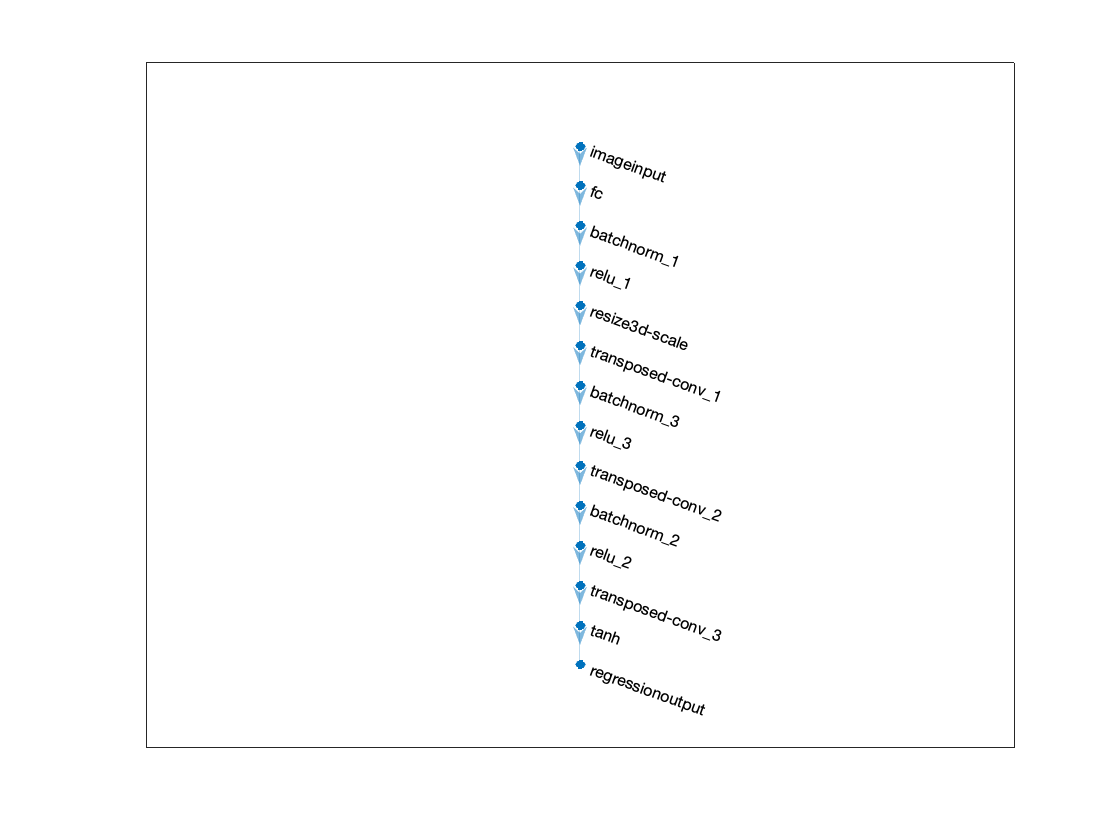

plot(layerGraph(layers));